# title

## heading

### heading 2

text

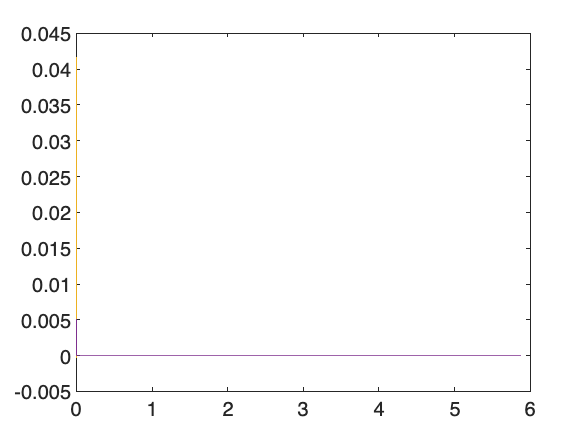

m=1;
cp=1+0*0.075;
cv=1+0*0.1;

G_nom = tf(cp, [m, cv, cp]);

% bode(G_nom);
margin(G_nom)

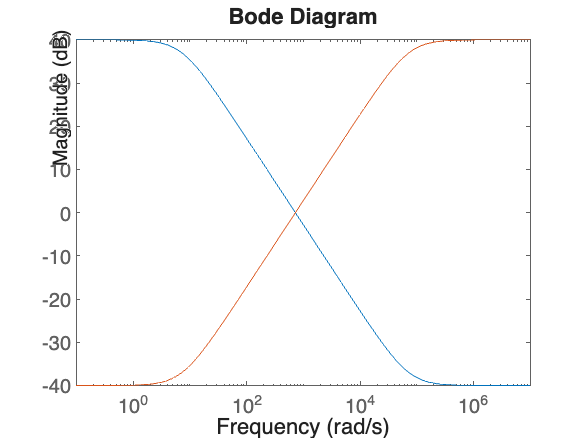

nyquist(G_nom);

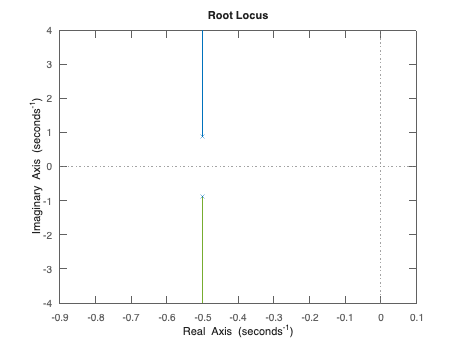

rlocus(G_nom);

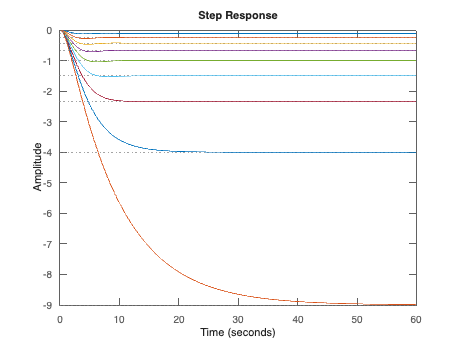


omega = 2*pi*1e5;
d = tf(omega, [1, 0, omega^2]);

% step = tf(1, [1, 0]);
for k=1:1:9
    % k= -k;
    % y = -((k*G_nom)/(1+k*G_nom))*d;
    step(((k*G_nom)/(1+k*G_nom)));
    hold on;
end

## a

higher K => close loop tracking better => more 

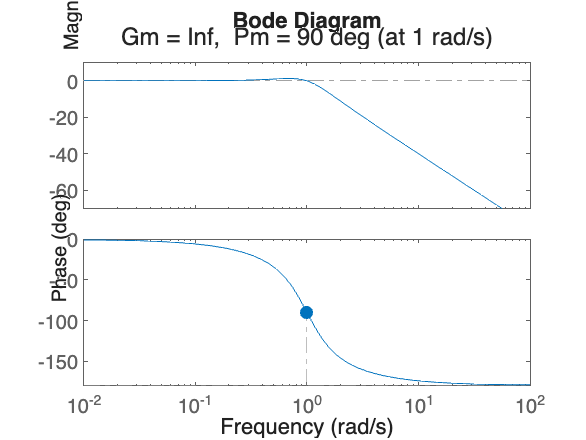

% % t = 0:0.01:10;
% t = linspace(0, 10, 1000);
% 
% [out, time]= lsim(G_nom, sin(t), t);
% plot(time, out);

delcp_range = [-0.075	0.075];
delcv_range = [-0.1	0.1];

w = logspace(1e-2, 1e2, 100);
% % s = 1i * w;

% s = tf('s');

figure
for delcp = delcp_range
    for delcv = delcv_range
        gain = ((delcp^2).*(w.^4) + (w.^2).*(delcp-delcv)^2)./((1-w.^2+w.^4).*((1+delcv)^2*w.^2 + (1+delcp-w.^2)));
        plot(w, gain)
        hold on;
    end
end

tau = 0.05;
X = tf(1, [tau^2, 2*tau, 1]);
s = tf('s');
W = 1/(0.5*s +1)^4;

G = [[X*s^2  -X  -X  0];
     [X (s^-2)*(1/X - X) -(s^(-2))*X (s^(-2))];
     [W*(1-X) -W*(s^(-2))*(1/X - X) W*(s^(-2))*X W*(-s^(-2))];
     [W*(s^2)*X W*(1-X) -W*X 0]];

% makeStateSpace(G)
ss(makeStateSpace(G), 'minimal')


ans =
 
  A = 
               x1         x2         x3         x4         x5         x6         x7         x8         x9        x10        x11        x12
   x1      -9.226     -4.857      1.025      12.77      25.81      -1.25    -0.6668     0.0803      1.168    -0.4935      1.507      7.258
   x2      -8.155     -5.366  -0.007495      10.08       17.1     0.4186     0.2809    0.04261      -4.27      3.684     -1.179      3.618
   x3       1.992      4.944     -6.232     -4.767     -7.923    -0.8604    -0.5776     -2.421    -0.3428      -2.17      2.208      2.907
   x4     -0.8727    -0.7717      1.517      -3.94     -5.814   -0.08303    -0.1956     0.5853     0.9077    -0.5845     0.3043     0.2144
   x5      0.7636     0.6753    -0.1756     -10.45     -18.72     0.3425    0.04388     0.4834     0.4799    0.08257   -0.05618   -0.06433
   x6       -0.33    -0.2918    0.07588     0.5122      1.559    -0.1842  -0.002216    -0.0571    0.03483    -0.4846      0.358     0.1759
   x7     -

figure
G_nom = tf(1, [1, 1, 1]);
% S = 1/G_nom;
dcp = -0.075;
dcv = 0.1;
w_cr = sqrt(dcp/(dcp+dcv));
w = tf('s');
W1 = makeweight(100, 6*pi, 0.01);

% H = makeweight(0.1, w_cr, 1.1);

W2 = (dcp*(s^2+s+1) - dcv*s -dcp)/((s^2 + s+ 1)*(s^2 + (1+dcv)*s +1 + dcp))


W2 =
 
             -0.075 s^2 - 0.175 s
  -------------------------------------------
  s^4 + 2.1 s^3 + 3.025 s^2 + 2.025 s + 0.925
 
Continuous-time transfer function.
Model Properties



% W2 = sqrt(w^2*(dcp^2*w^2 + (dcp+dcv)^2)/(w^4 - w^2 +1)/(((1-dcv)^2)*w^2 + (1+dcp-w^2)^2) )
    % (((1-heaviside(w-1i*w_cr))/(((1-dcv)^2)*w^2 + (1+dcp-w^2)^2)) + (heaviside(w-1i*w_cr)/(((1+dcv)^2)*w^2 + (1-dcp-w^2)^2)));
W3 = makeweight(0.01, 500*pi, 100);
P = augw(G_nom,W1,[],W3);
[K,CL,gamma] = hinfsyn(P); 
gamma

gamma = 0.1104

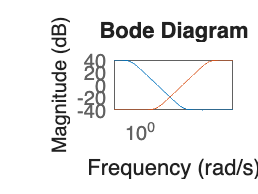


figure
% hinfsyn();
% mixsyn();
bodemag(W1, W2, W3)

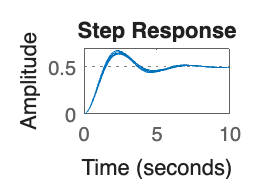


cp = ureal('cp', 1, 'PlusMinus', 0.075);
cv = ureal('cv', 1, 'PlusMinus', 0.1);
s = tf('s');
G_u = cp/(s^2 + cv*s + cp);
T = feedback(G_u*K, 1);
T_n = feedback(G_u, 1);
stepplot(usample(T_n, 10), 10)

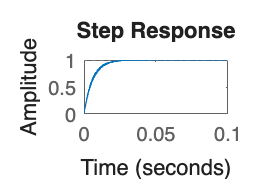

stepplot(usample(T, 10), .1)